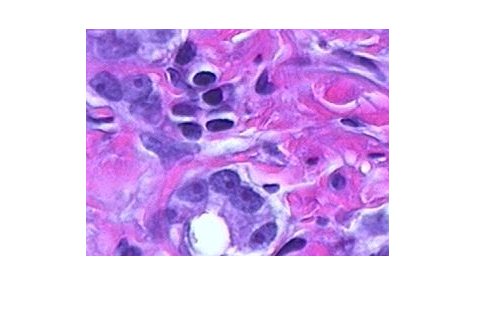

im = imread('hestain.png');
imshow(im)

%from RGB Color Space to L*a*b Color Space
lab_im = rgb2lab(im);

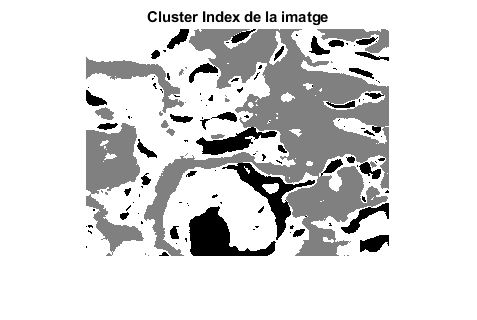

%classify colors in a*b* space using k-means Clustering
ab = lab_im(:,:,2:3);
ab = im2single(ab);
nColors = 3;

% repeat the clustering 3 times to avoid local minims
pixel_labels = imsegkmeans(ab,nColors,'NumAttempts',3);

imshow(pixel_labels,[])
title('Cluster Index de la imatge');

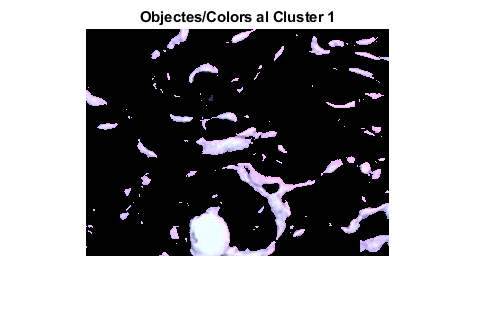

%creating images for each color in the image
mask1 = pixel_labels==1;
cluster1 = im .* uint8(mask1);
imshow(cluster1)
title('Objectes/Colors al Cluster 1');

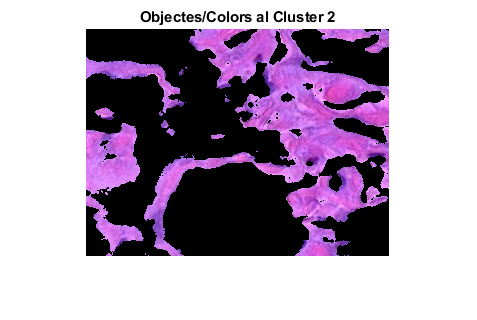


mask2 = pixel_labels==2;
cluster2 = im .* uint8(mask2);
imshow(cluster2)
title('Objectes/Colors al Cluster 2');

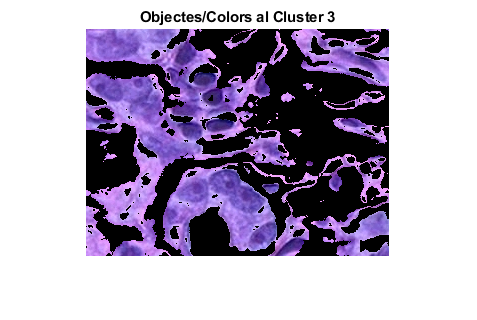


mask3 = pixel_labels==3;
cluster3 = im .* uint8(mask3);
imshow(cluster3)
title('Objectes/Colors al Cluster 3');

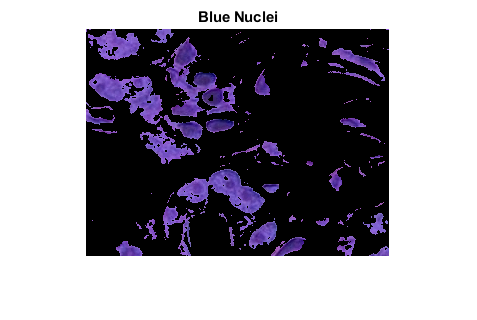


L = lab_im(:,:,1);
L_blue = L .* double(mask3);
L_blue = rescale(L_blue);
idx_light_blue = imbinarize(nonzeros(L_blue));


blue_idx = find(mask3);
mask_dark_blue = mask3;
mask_dark_blue(blue_idx(idx_light_blue)) = 0;

blue_nuclei = im .* uint8(mask_dark_blue);
imshow(blue_nuclei)
title('Blue Nuclei');